**TASK # 1**

**Make a 2-D Matrix to represent a Table.**

clc
clear all
close all
A = zeros(10,3); % Create a Matrix with Initial-Zero values with
                 % In (10,3) ; #of Rows=10 , #of Columns=3
for i = 1:10     % Number of Rows
    %i
    for j = 1:3  % Number of Columns
        %j
        B = input('Enter the Value for Entery A(i,j)');
        A(i,j) = B;
    end
end
%% For 2-D Matrix A :
% A(:,1) means: Access all Rows and 1st Column
% A(1,:) means: Access 1st Row and all Columns
% A or A(:,:) means: Acess all Rows and all Columns
A

A =      1     1     1
     2     2     2
     3     3     3
     4     4     4
     5     5     5
     6     6     6
     7     7     7
     8     8     8
     9     9     9
    10    10    10


**TASK # 2**

**Plot the given four relative functions for **$0\le \mathit{\mathbf{x}}\le 64\;$**and stepsize 0.5, on the same graph.**

- 
$$\mathit{\mathbf{y}}=\mathit{\mathbf{x}}$$


- 
$$\mathit{\mathbf{y}}=\mathit{\mathbf{x}}\left({\mathbf{log}}_2 \mathit{\mathbf{x}}\right)$$


- 
$$\mathit{\mathbf{y}}=\mathit{\mathbf{x}}{\left({\mathbf{log}}_2 \mathit{\mathbf{x}}\right)}^2$$


- 
$$\mathit{\mathbf{y}}={\mathit{\mathbf{x}}}^2$$


clc
clear all
close all
% Given Values of x:
x = 0:0.5:64;

%% Question#1
y = x;

%% Question#2
y1 = x.*(log2(x));

%% Question#3
y2 = x.*((log2(x)).^2);

%% Question#4
y3 = x.^2;

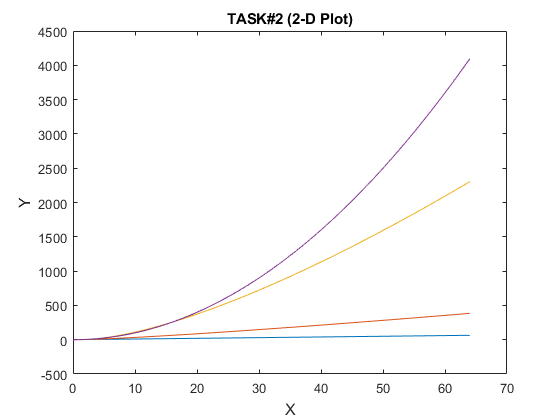

plot(x,y,x,y1,x,y2,x,y3)
title('TASK#2 (2-D Plot)')
xlabel('X','FontSize',12,'FontWeight','bold')
ylabel('Y','FontSize',12,'FontWeight','bold')

**TASK # 3**

**Given that, x = [1,2,3,4,5] and y = [6,7,8,9,10].**

**Find**                

- 
$$\sum_{\mathit{\mathbf{i}}=1}^5 {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} \sum_{\mathit{\mathbf{i}}=1}^5 {\mathit{\mathbf{y}}}_{\mathit{\mathbf{i}}}$$


- 
$$\sum_{\mathit{\mathbf{i}}=1}^5 {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} {\;\mathit{\mathbf{y}}}_{\mathit{\mathbf{i}}}$$


- 
$$\sum_{\mathit{\mathbf{i}}=1}^5 {\mathit{\mathbf{log}}}_{10} \left({\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} \right)$$


- 
$$\sqrt{\left.\sum_{\mathit{\mathbf{i}}=1}^5 {\left(5\mathit{\mathbf{x}}\right.}_{\mathit{\mathbf{i}}} +{\mathit{\mathbf{y}}}_{\mathit{\mathbf{i}}} \right)\mathbf{ }\mathbf{ }}$$


- 
$$\sum_{\mathit{\mathbf{i}}=1}^5 {\left|{2\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} -{5\mathit{\mathbf{y}}}_{\mathit{\mathbf{i}}} \right|}$$


- 
$${\mathit{\mathbf{e}}}^{\sum_{\mathit{\mathbf{i}}=1}^5 {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} }$$


clc
clear all
close all
% Given Values of x and y:
x = [1,2,3,4,5];
y = [6,7,8,9,10];

% Let Initial Values are:
Sx = 0;
Sy = 0;
Sxy = 0;
SLx = 0;
SSq = 0;
SAb = 0;
SEx = 0;

%% Question#1
for i = 1:5
    Sx = Sx + x(i);
    Sy = Sy + y(i);
end
Ans1 = Sx*Sy

Ans1 = 600

%% Question#2
for i = 1:5
    Sxy = Sxy + x(i)*y(i);
end
Ans2 = Sxy

Ans2 = 130

%% Question#3
for i = 1:5
    SLx = SLx + log10(x(i));
end
Ans3 = SLx

Ans3 = 2.0792

%% Question#4
for i = 1:5
    SSq = SSq + (5*x(i) + y(i));
end
Ans4 = sqrt(SSq)

Ans4 = 10.7238

%% Question#5
for i = 1:5
    SAb = SAb + abs((2*x(i)-5*y(i)));
end
Ans5 = SAb

Ans5 = 170

%% Question#6
for i = 1:5
    SEx = SEx + (x(i));
end
Ans6 = exp(SEx)

Ans6 = 1.1420e+26